# 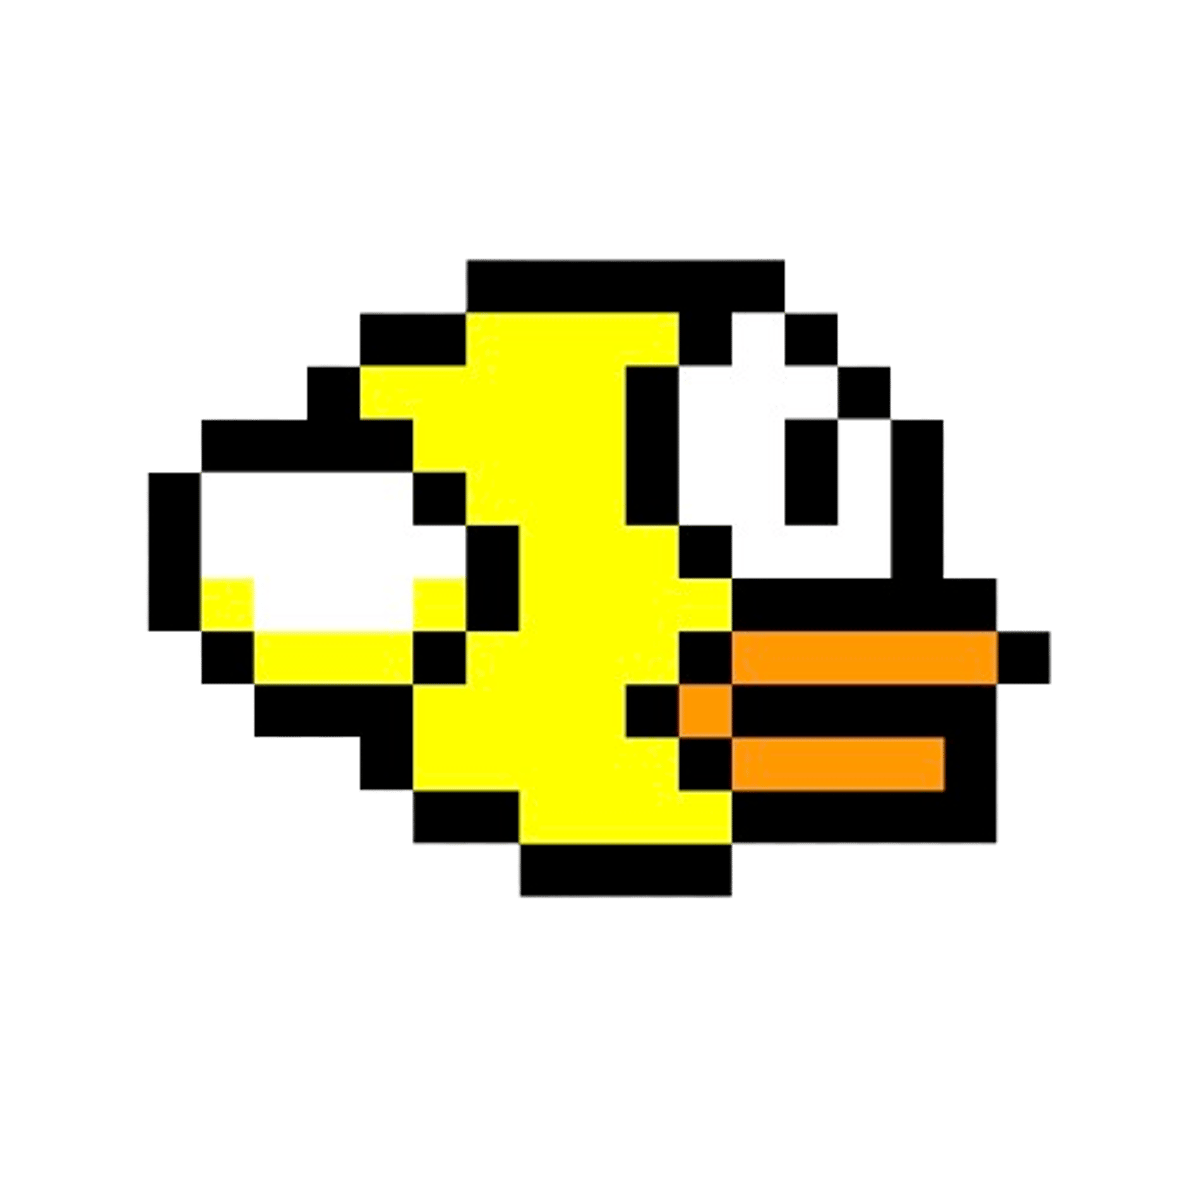

# Project: Altitude control of a Flappy Bird robot

## Part 2: Feedback control

## Plant parameters

Now that you have completed **Part 1 **of the project, you should have a good idea of the plant model structure, as well as the required closed-loop specifications. The final outstanding piece of information is the numerical parameters for your Flappy Bird robot. Each student will get their unique set of plant parameters, which will be determined based on your PeopleSoft number. As such, copying another student's feedback controller will likely lead to disaster!

The Flappy Bird game is packaged within the attached MATLAB toolbox, `FlappyBirdPart2.mltbx`. To play the game, you must first install this toolbox. To do this, ensure your MATLAB working directory is set to the project folder and that the `.mltbx` file is located in this folder. Then, execute the following command:

matlab.addons.install('FlappyBirdPart2.mltbx');

To run the game, initialise the application with the following code. Note that you need to also enter your PeopleSoft ID (your seven-digit numerical identifier), as each student's Flappy Bird robot will have different dynamic behaviour. You must run this section every time you reopen the project to reload your PeopleSoft number into the FlappyBird app and to retrieve your unique Flappy Bird parameters.

peopleSoftID =  %enter your seven-digit numerical ID

% Abitrary and non-descript controller to initialise game
s = tf('s');
G = 1+0*s;
save('ControllerG.mat', 'G')

app = FlappyBirdPart2(peopleSoftID);

The mass, $m$, and aerodynamic drag coefficient, $b$, will be used to form your open-loop plant model, $P(s)$. 

m = app.mFlappyBird;
b = app.bFlappyBird;
fprintf('The mass of your Flappy Bird robot is: %.3f kg', m)
fprintf('The aerodynamic drag of your Flappy Bird robot is: %.3f Ns/m', b)

### Defining the plant model

Using your plant model structure from **Part 1**, as well as the parameters above, you can now define your numerical plant model for $P(s)$. As a start, we will not model the effects of gravitational disturbance.

%Add plant model here
s = tf('s');
P = ?;

### Feedback control design

**Figure 3** describes the intended feedback control structure, where $P(s)$ is the plant model, $G(s)$ is the feedback controller to be designed, $R(s)$ is the reference altitude for the Flappy Bird robot, $Y(s)=Z(s)$ is the altitude of the robot, and $D(s)$ is the gravitational acceleration disturbance acting on the system.

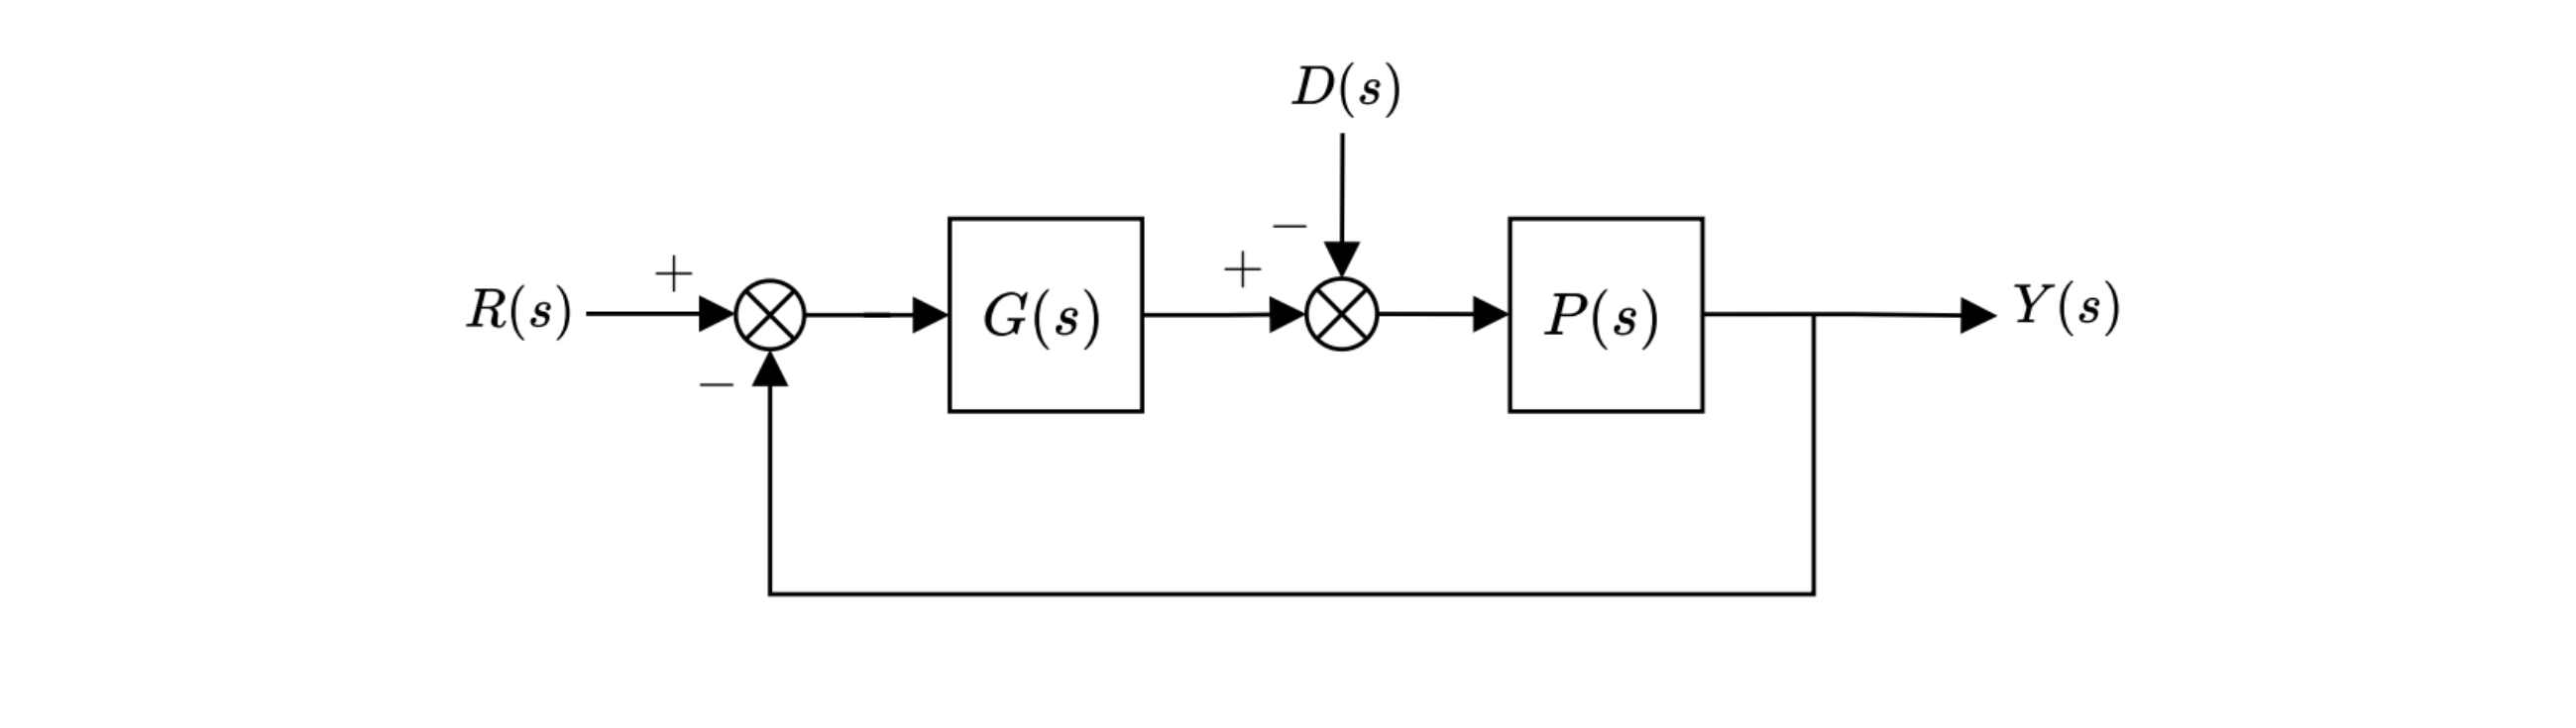

**Figure 3**: Block diagram of intended feedback control approach.

With all the requisite information in hand, you can now begin to design an appropriate feedback controller. Specifically, you must use the simplified *stay-above* and *stay-below *bounds, as well as the steady-state error requirement, in order to design feedback controller $G(s)$. We will also ignore the gravitational disturbance for now, although, our controller should still cater for zero-error tracking at steady-state for step-like disturbances.

####  **  Task:** Design an appropriate controller that simultaneously meets all the specifications defined in Part 1.

Use the design approach outlined in **Chapter 11** and **Chapter 12** of the course notes. The design process should not come down to guessing correct parameters! To assist with the design, you are provided with the following skeleton code to generate the appropriate log-polar plot diagram, as well as code to assess the closed-loop step response behaviour.

s = tf('s');

% G = ?
L = P*G; %loop transfer function. Previously code block needs to be run for P to be defined in workspace

%Specifications
Ts = ?;
OS = ?;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

%Boundaries
Ma = ?; %stay-below bound
Mb = ?; %stay-above bound

figure, hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
[magL,phiL] = nichols(L,{1e-3,1e3});
plot(squeeze(phiL),squeeze(20*log10(magL)))

plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')
xlim([-360,0]),ylim([-100,50])

#### **  Question 1: Output a log-polar plot with **$G(s)=1$, **demonstrating your design approach to meet the **design specifications.** Ensure your log-polar plot displays the relevant design boundary regions, the frequency response locus of **$L(j\omega)=P(j\omega)$, and the relevant frequency point(s) of interest.

*Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, e.g.: Log-polar plot_SMTJOH999.*

*Hint: If you click on an image, there is an Export option that allows you to save the image.*

%Code block (if required)


Setting $G(s)=1$ allows you to see what is required of the controller in terms of gain and phase. Do not be surprised that your system is currently not within spec — that is to be expected with $G(s)=1$. You will now proceed to design an appropriate controller that meets all the design specifications, based on the process outlined in **Chapter 12**.

#### **  Question 2: Output a log-polar plot with your designed controller included**, **demonstrating your adherence to the **design specifications.** Ensure your log-polar plot displays the relevant design boundary regions, the frequency response locus of **$L(j\omega)=P(j\omega)G(j\omega)$, and the relevant frequency point(s) of interest.

*Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, e.g.: Log-polar plot_SMTJOH999.*

*Hint: If possible, give some "headroom" in terms of meeting the design requirements, as this will assist with any uncertainty in the actual Flappy Bird game.*

%Code block (if required)


#### **  Question 3: Provide an explanation as to why you chose the particular feedback controller structure.**

*Format: Your answer should include information about Type number, phase lead, and gain requirements in order to meet the performance specifications.*

#### **  Question 4: Output a unit step response of the Flappy Bird robot**, applied at $t=0$ seconds, showing adherence to the time-domain specifications.

    *Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, e.g.: Step response_SMTJHN001. *

%Code block (if required)


### Implementation in Flappy Bird game

Now that you have designed a feedback controller and shown it to work in simulation (in idealised conditions), it is time to test whether your Flappy Bird will be able to make it through all obstacles.

With your feedback controller defined in `MATLAB` as `G`, run the following code. The code block will effectively load your designed feedback controller into the game so that it can be automatically applied. Note that you must set the game to "feedback mode" in order to assess the closed-loop performance of the Flappy Bird robot.

%Code block to save G to .mat file and then execute game.
save('controllerG.mat','G')

#### **  Question 5: Output an image of the Flappy Bird game after completing the highest number of obstacles. **

*Format: Your answer should be a figure (.png or .jpeg)*

*Hint: You can save an image from the Flappy Bird game by navigating to the control panel, selecting *`File`*, then *`Save As...`* and then selecting either *`.png`* or *`.jpeg`* as the file type.*

%Code block (if required)

Once finished with the game, first toggle the **Flappy Bird** switch back to ***Exit***. After the game window closes, execute the command below to close the application completely. 

delete(app)

**  Question 6: Submit your completed Project_Part2.mlx. The file name must be appended with your student number, e.g. Project_Part2_SMTJOH999.slx.** 

*This concludes the project.*